grupe.pavardes = {'Jonaitis', 'Petraitis', 'Kazlauskaitė'}; 
grupe.amzius = [20, 21, 20]; 


Pradinė struktūra:


disp(grupe);

    pavardes: {'Jonaitis'  'Petraitis'  'Kazlauskaitė'}
      amzius: [20 21 20]



grupe_pakeista = orderfields(grupe, {'amzius', 'pavardes'});

disp('Struktūra pakeitus laukų tvarką:');

Struktūra pakeitus laukų tvarką:


disp(grupe_pakeista);

      amzius: [20 21 20]
    pavardes: {'Jonaitis'  'Petraitis'  'Kazlauskaitė'}


clear
format compact;

syms b;

lentele = zeros(10,3);

while true
    
    x = input('x =')
    y = input('y =')

    if x == 0 && y == 0
        break
    end

    for n = 1:10

        lygtis1 = subs(n.*(cos(b)+1i*sin(b)).^n,b,atan(y/x));
        lygtis2 = subs((cos(n*b)+1i*sin(n*b)),b,atan(y/x));

        skirtumas = lygtis1 - lygtis2;

        lentele(n,1) = lygtis1;
        lentele(n,2) = lygtis2;
        lentele(n,3) = skirtumas;

       
    end 
    disp('kaire                  desine                skirtumas')
    disp(lentele);
end

x = 5

y = 7

kaire                  desine                skirtumas


   0.5812 + 0.8137i   0.5812 + 0.8137i   0.0000 + 0.0000i
  -0.6486 + 1.8919i  -0.3243 + 0.9459i  -0.3243 + 0.9459i
  -2.8748 + 0.8577i  -0.9583 + 0.2859i  -1.9165 + 0.5718i
  -3.1585 - 2.4543i  -0.7896 - 0.6136i  -2.3689 - 1.8408i
   0.2017 - 4.9959i   0.0403 - 0.9992i   0.1613 - 3.9967i
   5.0191 - 3.2877i   0.8365 - 0.5479i   4.1826 - 2.7397i
   6.5247 + 2.5355i   0.9321 + 0.3622i   5.5926 + 2.1733i
   1.9762 + 7.7521i   0.2470 + 0.9690i   1.7292 + 6.7831i
  -5.8044 + 6.8781i  -0.6449 + 0.7642i  -5.1595 + 6.1139i
  -9.9675 - 0.8060i  -0.9967 - 0.0806i  -8.9707 - 0.7254i


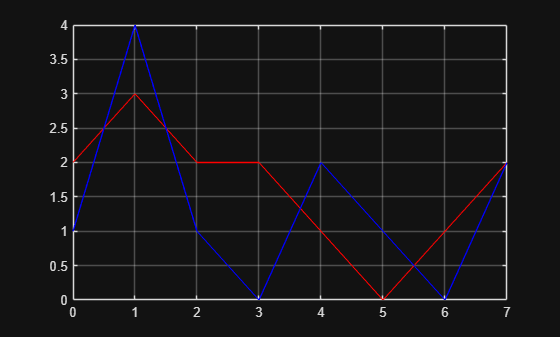

clear

n=0;
nplot = [0];

skaic1= round(rand*3);
skaic2 = round(rand*5);

masyv1 = [];
masyv2 = [];

masyv1(end+1) = skaic1;
masyv2(end+1) = skaic2;

while skaic1 ~= skaic2;
    
    n = n+1;
    nplot(end+1) = n;
    skaic1= round(rand*3);
    skaic2 = round(rand*5);
    masyv1(end+1) = skaic1;
    masyv2(end+1) = skaic2;

end

plot(nplot,masyv1,Color="r");
hold on;
plot(nplot,masyv2,Color="b");
hold off;
grid on;